## Load Hopkins data

%subsample frames to simulate high-rank setting
load data/hopkins_1R2RC_truth.mat
s = size(x,2); %num data points
F = 6;
frames = floor(linspace(1,size(x,3)-1,F)); %even spacing between frames
n = 2*F;
Xtrue = reshape(permute(x(1:2,:,frames),[1 3 2]),n,s);
disp("done")

done


disp(s)

   459



## Subsample data uniformly at random

(in pairs of (x,y) coordinates)

rng(10); %fix random seed
missrate = 0.3;
sampmask_sm = false(F,s);
rind = randperm(F*s);
rv = round((1-missrate)*F*s);
sampmask_sm(rind(1:rv)) = true;
sampmask = false(n,s);
sampmask(1:2:(n-1),:) = sampmask_sm;
sampmask(2:2:n,:) = sampmask_sm;
samples = Xtrue(sampmask);
Xinit = zeros(n,s);
Xinit(sampmask) = samples;
disp("done")

done


## Run low-rank matrix completion (LRMC) for baseline

options_nn.lambda = 1e8;
options_nn.mu = 1;
options_nn.niter = 1000;
Xlrmc = lrmc_admm(Xinit,sampmask,samples,options_nn);
%Xlrmc = lrmc_cvx(sampmask,samples); % CVX version
fprintf('LRMC NRMSE = %1.2e\n',norm(Xlrmc-Xtrue,'fro')/norm(Xtrue,'fro'));

LRMC NRMSE = 1.07e-02


disp("done")

done


## Run variety-based matrix completion (VMC)

options = [];
options.d = 2; %kernel degree
options.c = 1; %use inhomogeneous kernel for affine union of subspaces model
options.niter = 3000;
[Xvmc,cost,update,error] = vmc(Xinit,sampmask,samples,options,Xtrue);

VMC set options.eigcomp='lift-svd' based on problem size
VMC reached exit tolerance at iter 2322


fprintf('VMC NRMSE = %1.2e\n',norm(Xvmc-Xtrue,'fro')/norm(Xtrue,'fro'));

VMC NRMSE = 1.43e-03


disp("done")

done


## Display columnwise errors

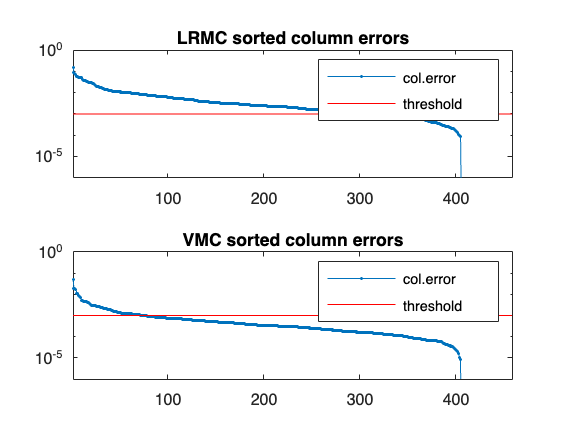

figure(1);
colerr_vmc = zeros(1,s);
colerr_lrmc = zeros(1,s);
for j = 1:s
    colerr_vmc(j) = norm(Xvmc(:,j)-Xtrue(:,j))/norm(Xtrue(:,j));
    colerr_lrmc(j) = norm(Xlrmc(:,j)-Xtrue(:,j))/norm(Xtrue(:,j));
end
[colerr_vmc,idx] = sort(colerr_vmc,'descend');
[colerr_lrmc,idx] = sort(colerr_lrmc,'descend');
errthresh = 1e-3;

subplot(2,1,1);
semilogy(colerr_lrmc,'.-'); title('LRMC sorted column errors');
hold on
line([0 s],[errthresh errthresh],'Color','red');
hold off
axis([1 s 1e-6 1]);
legend('col.error','threshold');
subplot(2,1,2);
semilogy(colerr_vmc,'.-'); title('VMC sorted column errors');
hold on
line([0 s],[errthresh errthresh],'Color','red');
hold off
legend('col.error','threshold');
axis([1 s 1e-6 1]);

fprintf('LRMC recovered %2.1f%% columns (%d of %d) with err < %1.1e\n',(nnz(colerr_lrmc < errthresh)/s)*100,nnz(colerr_lrmc < errthresh),s,errthresh);

LRMC recovered 33.3% columns (153 of 459) with err < 1.0e-03


fprintf('VMC recovered %2.1f%% columns (%d of %d) with err < %1.1e\n',(nnz(colerr_vmc < errthresh)/s)*100,nnz(colerr_vmc < errthresh),s,errthresh);

VMC recovered 84.7% columns (389 of 459) with err < 1.0e-03
